## Tutorial 6 - Problem 1a, step input, first order system

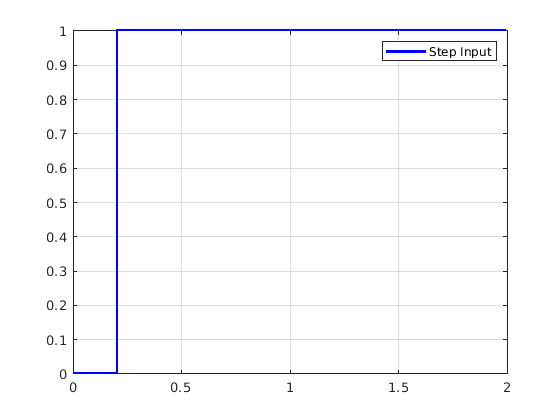

clc; clear all; close all;

K = 3; % Gain
tau = 0.3; % s

simTime = 2; % s

stepStart = 0.2; % s

rampStart = 0.2; % s
rampEnd = 0.7;   % s

xMax = 1;

t = 0; % s
dt = 10^-5; % s
idx = 1; % Counter

y = 0;

while(t <= simTime)

    % Calculations

    % If statement for step input
    if(t <= stepStart)
        x = 0;
    else
        x = xMax;
    end

    yDot = 1/tau * (K*x-y); % First Order System in Time Domain (state variable y)

    % Logging
    time_plot(idx) = t;
    y_plot(idx) = y;
    x_plot(idx) = x;

    % Time Integrate
    y = y + yDot * dt;

    t = t + dt;
    idx = idx + 1;

end

% Plot input
plot(time_plot,x_plot, 'b', 'LineWidth', 2)
legend("Step Input")
grid

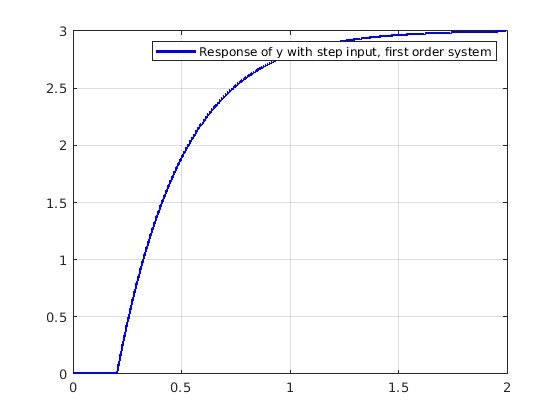


% Plot response
plot(time_plot, y_plot, 'b', 'LineWidth', 2)
legend("Response of y with step input, first order system")
grid

## Tutorial 6 - Problem 1a, ramp input, first order system

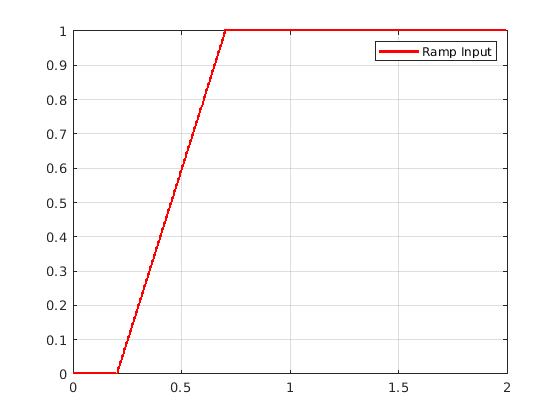

clc; clear all;

K = 3; % Gain
tau = 0.3; % s

simTime = 2; % s

stepStart = 0.2; % s

rampStart = 0.2; % s
rampEnd = 0.7;   % s

xMax = 1;

t = 0; % s
dt = 10^-5; % s
idx = 1; % Counter

y = 0;

while(t <= simTime)

    % Calculations

    % If statement for ramp input
    if(t <= stepStart)
        x = 0;
    elseif(t <= rampEnd)
        x = (t-rampStart)/(rampEnd-rampStart) * xMax;
    else
        x = xMax;
    end

    yDot = 1/tau * (K*x-y); % First Order System in Time Domain (state variable y)

    % Logging
    time_plot(idx) = t;
    y_plot(idx) = y;
    x_plot(idx) = x;

    % Time Integrate
    y = y + yDot * dt;

    t = t + dt;
    idx = idx + 1;

end

% Plot input
plot(time_plot,x_plot, 'r', 'LineWidth', 2)
legend("Ramp Input")
grid

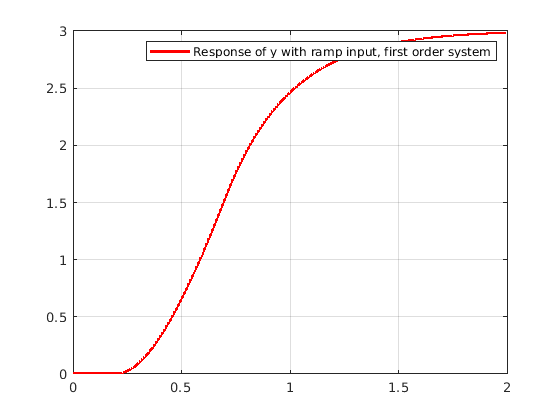


% Plot result
plot(time_plot, y_plot, 'r', 'LineWidth', 2)
legend("Response of y with ramp input, first order system")
grid

## Tutorial 6 - Problem 1b, step input, second order system

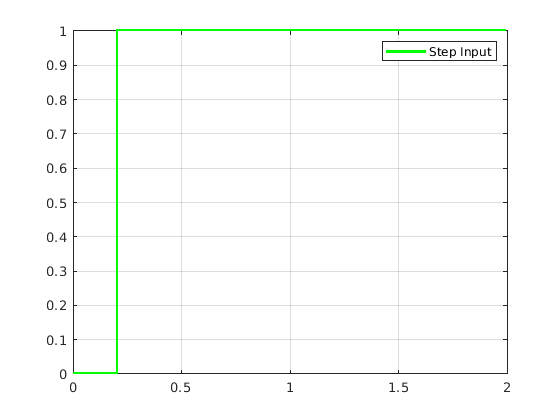

clc; clear all;

K = 250; % Gain
omega_sys = 10; % rad/s
zeta = 0.3;

simTime = 2; % s

stepStart = 0.2; % s

rampStart = 0.2; % s
rampEnd = 0.7;   % s

xMax = 1;

t = 0; % s
dt = 10^-5; % s
idx = 1; % Counter

y = 0;
yDot = 0;

while(t <= simTime)

    % Calculations

    % If statement for step input
    if(t <= stepStart)
        x = 0;
    else
        x = xMax;
    end

    yDotDot = omega_sys^2 * (K * x - ((2*zeta)/omega_sys) * yDot - y); % Second Order System in Time Domain (state variables y and yDot)

    % Logging
    time_plot(idx) = t;
    y_plot(idx) = y;
    x_plot(idx) = x;

    % Time Integrate
    yDot = yDot + yDotDot * dt;
    y = y + yDot * dt;

    t = t + dt;
    idx = idx + 1;

end

% Plot input
plot(time_plot,x_plot, 'g', 'LineWidth', 2)
legend("Step Input")
grid

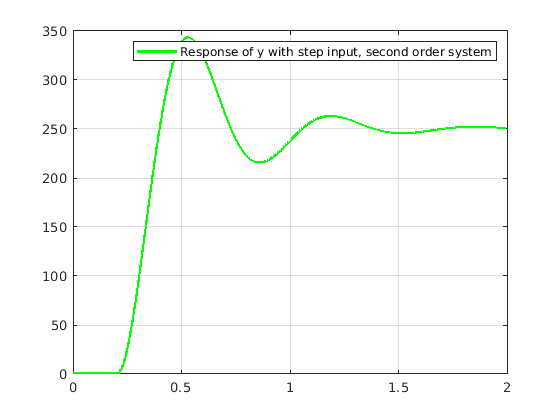


% Plot response
plot(time_plot, y_plot, 'g', 'LineWidth', 2)
legend("Response of y with step input, second order system")
grid

## Tutorial 6 - Problem 1b, ramp input, second order system

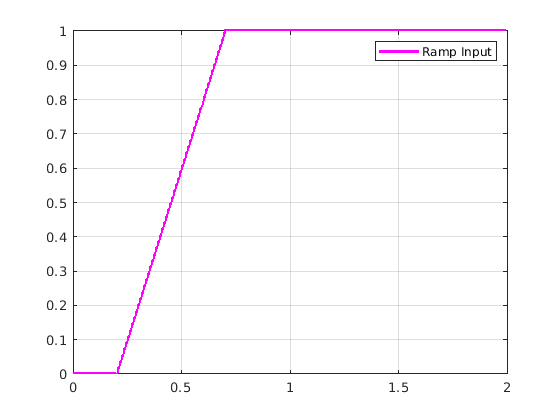

clc; clear all;

K = 250; % Gain
omega_sys = 10; % rad/s
zeta = 0.3;

simTime = 2; % s

stepStart = 0.2; % s

rampStart = 0.2; % s
rampEnd = 0.7;   % s

xMax = 1;

t = 0; % s
dt = 10^-5; % s
idx = 1; % Counter

y = 0;
yDot = 0;

while(t <= simTime)

    % Calculations

    % If statement for ramp input
    if(t <= stepStart)
        x = 0;
    elseif(t <= rampEnd)
        x = (t-rampStart)/(rampEnd-rampStart) * xMax;
    else
        x = xMax;
    end

    yDotDot = omega_sys^2 * (K * x - ((2*zeta)/omega_sys) * yDot - y); % Second Order System in Time Domain (state variables y and yDot)

    % Logging
    time_plot(idx) = t;
    y_plot(idx) = y;
    x_plot(idx) = x;

    % Time Integrate
    yDot = yDot + yDotDot * dt;
    y = y + yDot * dt;

    t = t + dt;
    idx = idx + 1;

end

% Plot input
plot(time_plot,x_plot, 'm', 'LineWidth', 2)
legend("Ramp Input")
grid

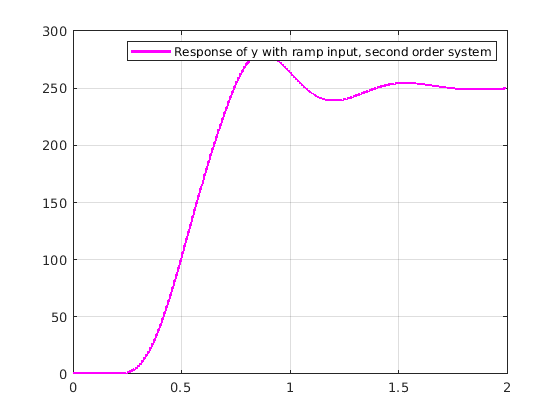


% Plot result
plot(time_plot, y_plot, 'm', 'LineWidth', 2)
legend("Response of y with ramp input, second order system")
grid